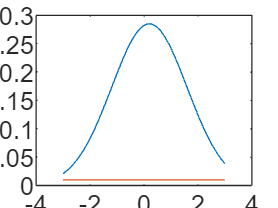

m = 0.2;
sig = 1.4;
x=linspace(-3,3);
f=@(x) 1/(sqrt(2*pi)*sig)*exp(-(1/(2*sig^2)*(x-m).^2));

plot(x,f(x),[x(1),x(end)],[0.01,0.01])

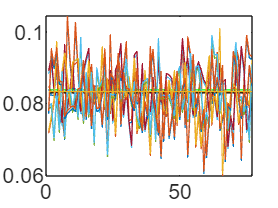

SOK = 77;
r = [];
for s=1:SOK
    N = 100;
    x = rand(1,N);
    t = sum((x-mean(x)).^2);
    r=[r,[t/N;t/(N-1)]];
    
end

plot(1:SOK,r(1,:),1:SOK,r(2,:),[1,SOK],[1/12,1/12])
hold on;

% plot([1,SOK],[mean(r(1,:)),mean(r(1,:))], "k")
%plot([1,SOK],[mean(r(2,:)),mean(r(2,:))], "g")
hold off;

mean(r(1,:))

ans = 0.0815

1/12

ans = 0.0833

mean(r(2,:))

ans = 0.0824




% sum((x-mean(x)).^2)/(N-1)
% xx = (x-mean(x))/std(x);
% histogram(xx);